# Putain de BAR à la con

## Adhérence

% clear all
% close all

g = 9.81; % Pesanteur (m/s²)

% Pilote
m_p = 75; % Masse du pilote (kg)
h_g_p = 0.42; % Hauteur du centre de gravite du pilote (m)

% Base roulante
m_v = 222; % Masse du vehicule (kg)
h_g_v = 0.3; % Hauteur du centre de gravite de la voiture (m)
emp = 1.575; % Empattement (m)
rep = 0.55; % Masse sur l'essieu arrière en statique (%)
m=m_v+m_p

m = 297

h_g = (m_v*h_g_v+m_p*h_g_p)/m

h_g = 0.3303

% Pneumatiques
% Pas de glissement
coeff_adh = 1.55;
sl =0;
coeff_roul = 0.01; % Coefficient de resistance au roulement du pneu
cx=0.665;

%Suspension
Kf=15800;%raideur ressort avant N/m
Kr=12100;%raideur ressort arrièreN/m


## Modèle grossier

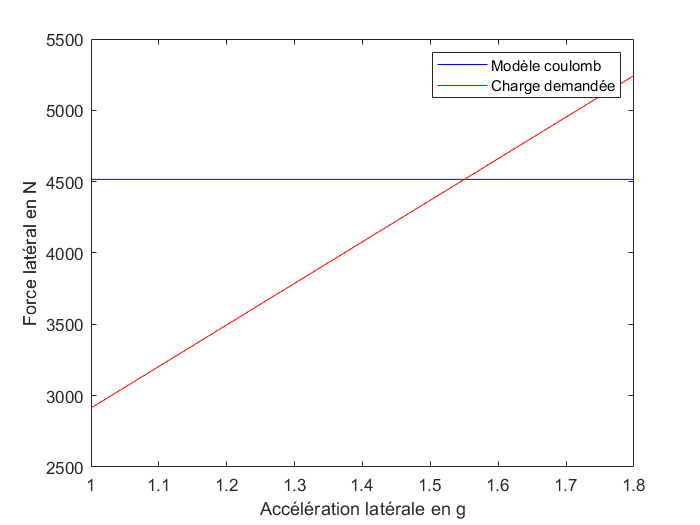

A=[1:0.05:1.8];
Fcoulomb=coeff_adh*m*g.*ones(1,length(A));
Fdemande=m.*A*g;

plot(A,Fcoulomb,'b',A,Fdemande,'r')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Modèle coulomb','Charge demandée')

## Modele AV/AR

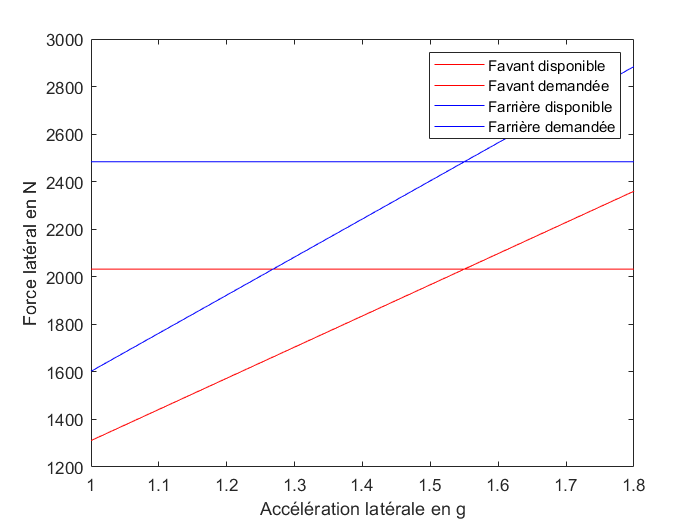

Fav=m*(1-rep).*A*g;
Far=m*rep.*A*g;
Favcoulomb=coeff_adh*m*(1-rep)*g.*ones(1,length(A));
Farcoulomb=coeff_adh*m*rep*g.*ones(1,length(A));

plot(A,Fav,'r',A,Favcoulomb,'r',A,Far,'b',A,Farcoulomb,'b')
xlabel('Accélération latérale en g')
ylabel('Force latéral en N')
legend('Favant disponible','Favant demandée','Farrière disponible','Farrière demandée')

L'arrière décroche en première => sur-vireur

## Modele Raideur anti-roulis


$$F_{\phi}=$$


On prend les raideurs des suspensions de Valkiryz

## Simu Décrochage de l'avant 1 BAR à l'avant

lf = linspace(0,10000,10);
Accel_d=zeros(1,length(lf));

for i=1:length(lf);
    a=1;
    Ff=m*(1-rep)*g+((emp^2*Kf+2*lf(i))/(emp^2*(Kf+Kr)+2*lf(i)))*h_g/emp*(1-rep)*m*a*g;
    while Ff*coeff_adh>m*(1-rep)*a;
        Ff=m*(1-rep)*g+((emp^2*Kf+2*lf(i))/(emp^2*(Kf+Kr)+2*lf(i)))*h_g/emp*(1-rep)*m*a*g;
        a=a+0.01;
    end
    Accel_d(i)=a;
end
plot(lf,Accel_d)
xlabel('Raideur BAR')
ylabel('Accel décrochage AV')

